## II/ Méthodes des triangles:

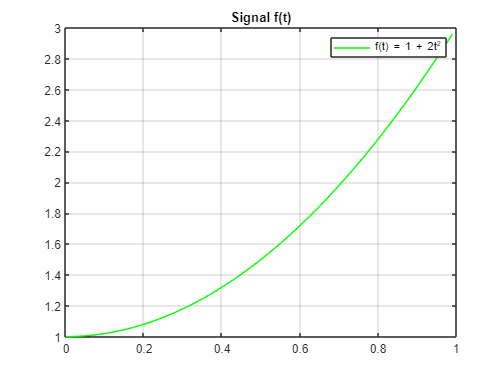

clc;
close; %ferme les anciennes figures
clear; %efface l'ancien workspace

a = 0;
b = 1;
n = 100;
dt = (b-a) / n;
t = (0:n-1)*dt;

f=1+2*t.^2; %calcul de la fonction

plot(t,f,'g');
title("Signal f(t)"); %donne un titre au graphe
legend("f(t) = 1 + 2t^2");
grid on;


R = sum(f .* dt) %calcul de l'aire R

R = 1.6567

## IV/ Méthodes des trapèzes:

T = ( dt * ( (f(1) + f(n))/2 + sum(f) ) ) % calcul de l'aire T

T = 1.6765

## V/ Méthode de Simpson:

N = 50; %nombre d'intervalles
P = 2 * N + 1; %nombre de points
DT = (b-a) /N;
T = (0:P-1)*DT/2; 
F = 1+2*T.^2; %calcul de la fonction

Somme1 = 0; %première somme de la méthode de simpson
Somme2 = 0; %deuxième somme de la méthode de simpson
for i = 1:N
    Somme1 = Somme1 + F(2 * i);
    Somme2 = Somme2 + F(2 * i - 1) ;
end
S = DT/6 * ( F(1) + 2 *Somme1 + 4 * Somme2 + F(end)) %calcul de l'aire de S

S = 1.6667